clear; close all; clc;

%% 1. CONFIGURATION & PARAMÈTRES
% ---------------------------------------------------------
% A. Chemin du Fichier (Adapter selon ton dossier)
filename ='Circuits_Data/de-1927.geojson';
ds = 2.0; % Pas de discrétisation (mètres)

% B. Véhicule (Modèle F1 Hybride)
m = 750;           % Masse (kg)
P_max = 700000;    % Puissance Moteur (Watts) ~ 1000ch
F_max = 25000;     % Traction max mécanique (Basse vitesse)
F_brake = 42000;   % Force de freinage max (N)
v_top_speed = 340 / 3.6; % Vitesse max absolue (m/s)

% C. Aérodynamisme (CRUCIAL pour F1)
rho = 1.225;       % Densité air (kg/m^3)
Area = 1.6;        % Surface frontale (m^2)
Cd = 1.2;          % Coeff Traînée (Drag) -> Freine la voiture
Cl = 5.2;          % Coeff Portance (Downforce) -> Colle la voiture au sol

% D. Paramètres Pneus & Sol
mu_base = 1.9;     % Friction de base (Grip mécanique)
% Pour le calcul du Sideslip (Papier Tang et al. 2020)
lf = 1.95; lr = 1.65; % Distances essieu avant/arrière au centre de gravité
Cr = 190000;       % Rigidité de dérive (Cornering Stiffness N/rad)

%% 2. GÉNÉRATION DE LA PISTE (GeoJSON + Splines)
% ---------------------------------------------------------
fprintf('Chargement du circuit : %s...\n', filename);

Chargement du circuit : Circuits_Data/de-1927.geojson...



% A. Lecture et Extraction
try
    jsonText = fileread(filename);
    data = jsondecode(jsonText);
    if isfield(data, 'features'), raw = data.features(1).geometry.coordinates;
    else, raw = data.geometry.coordinates; end
    lon = raw(:,1); lat = raw(:,2);
catch
    error('Fichier introuvable ou mauvais format. Vérifie le chemin !');
end

% B. Conversion GPS -> Mètres
lat0 = lat(1); lon0 = lon(1); R = 6371000;
x_raw = R * deg2rad(lon - lon0) * cos(deg2rad(lat0));
y_raw = R * deg2rad(lat - lat0);

% Fermeture de la boucle
if norm([x_raw(1)-x_raw(end), y_raw(1)-y_raw(end)]) > 5
    x_raw(end+1) = x_raw(1); y_raw(end+1) = y_raw(1);
end

% C. Nettoyage et Lissage (Splines)
d2 = diff(x_raw).^2 + diff(y_raw).^2;
is_moving = [true; d2 > 1e-5]; % Filtre les points doublons
x_c = x_raw(is_moving); y_c = y_raw(is_moving);

% Interpolation Spline
dist_steps = sqrt(diff(x_c).^2 + diff(y_c).^2);
t_raw = [0; cumsum(dist_steps)];
pp_x = spline(t_raw, x_c); pp_y = spline(t_raw, y_c);

S = 0 : ds : t_raw(end); % Nouveau vecteur distance régulier
x_track = ppval(pp_x, S); y_track = ppval(pp_y, S);

%% 2-BIS. OPTIMISATION DE LA TRAJECTOIRE (RACING LINE)
% ---------------------------------------------------------
fprintf('Calcul de la Racing Line (Largeur piste utilisée)...\n');

Calcul de la Racing Line (Largeur piste utilisée)...



% Paramètres de la piste
track_width = 10.0; % Largeur de piste F1 standard (mètres)
safe_margin = 1.0;  % Marge de sécurité (ne pas toucher l'herbe) (m)
allowable_width = (track_width / 2) - safe_margin;

% Algorithme "Apex Cutting" (Lissage itératif)
% On considère la ligne centrale comme un élastique qu'on tend.
x_race = x_track; 
y_race = y_track;
N_pts = length(x_race);

n_iter = 100; % Nombre d'itérations de lissage
alpha = 0.5;  % Facteur de lissage (0 à 1)

for k = 1:n_iter
    for i = 2:N_pts-1
        % 1. Trouver le milieu entre le point précédent et suivant
        x_mid = (x_race(i-1) + x_race(i+1)) / 2;
        y_mid = (y_race(i-1) + y_race(i+1)) / 2;
        
        % 2. Déplacer le point actuel vers ce milieu (Lissage)
        x_new = (1-alpha)*x_race(i) + alpha*x_mid;
        y_new = (1-alpha)*y_race(i) + alpha*y_mid;
        
        % 3. CONTRAINTE : Rester dans les limites de la piste
        % On calcule la distance par rapport au CENTRE ORIGINAL (x_track, y_track)
        dist_from_center = sqrt((x_new - x_track(i))^2 + (y_new - y_track(i))^2);
        
        % Si on sort de la piste, on ramène le point au bord
        if dist_from_center > allowable_width
            % Vecteur normalisé du centre vers le point nouveau
            angle = atan2(y_new - y_track(i), x_new - x_track(i));
            x_new = x_track(i) + allowable_width * cos(angle);
            y_new = y_track(i) + allowable_width * sin(angle);
        end
        
        x_race(i) = x_new;
        y_race(i) = y_new;
    end
end

% IMPORTANT : Remplacer les coordonnées utilisées pour le calcul de vitesse
% On garde une copie du centre pour l'affichage, mais la physique utilise la Racing Line
x_center = x_track; y_center = y_track; % Sauvegarde
x_track = x_race;   y_track = y_race;   % La "piste" devient la trajectoire opti

% Recalculer la distance S sur la nouvelle trajectoire (elle est plus courte !)
ds_new = sqrt(diff(x_track).^2 + diff(y_track).^2);
S = [0, cumsum(ds_new)];
% On ré-interpole pour garder un pas constant ds (important pour l'intégration)
% (Optionnel si ds est petit, mais plus propre)
% D. Courbure
dx = Gradient(x_track, ds); dy = Gradient(y_track, ds);
ddx = Gradient(dx, ds); ddy = Gradient(dy, ds);
curvature = (dx.*ddy - dy.*ddx) ./ (dx.^2 + dy.^2).^(1.5);
curvature(isnan(curvature)) = 0;
% Filtrage des pics de courbure irréalistes (artefacts splines)
curvature(abs(curvature) > 0.15) = 0.15 * sign(curvature(abs(curvature) > 0.15));

%% 3. OPTIMISATION (Aero + Cercle Friction)
% ---------------------------------------------------------
fprintf('Optimisation en cours (Modèle Aero + Friction Circle)...\n');

Optimisation en cours (Modèle Aero + Friction Circle)...


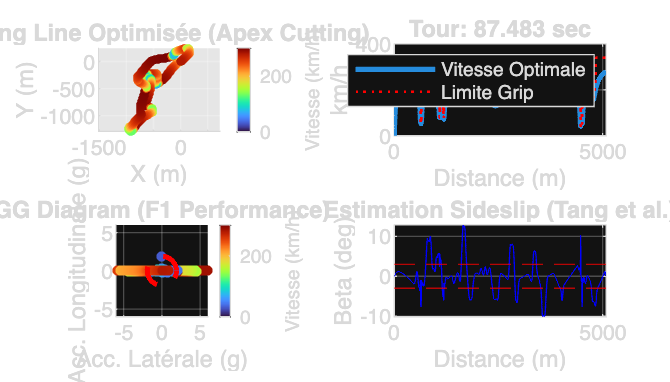

N = length(S);

% --- A. Limite de Vitesse Statique (Virage avec Downforce) ---
% Équation : m*v^2/R <= mu * (mg + 0.5*rho*S*Cl*v^2)
% On isole v^2 : v^2 * (m/R - mu*0.5*rho*S*Cl) <= mu*mg
v_limit = zeros(1, N);
aero_factor = 0.5 * rho * Area * Cl;

for i = 1:N
    k = abs(curvature(i));
    if k < 1e-5
        v_limit(i) = v_top_speed;
    else
        denom = (m * k) - (mu_base * aero_factor);
        if denom <= 0 
            % Downforce suffisante pour passer à fond (Théorique)
            v_limit(i) = v_top_speed; 
        else
            v_sq = (mu_base * m * 9.81) / denom;
            v_limit(i) = sqrt(max(0, v_sq));
        end
    end
end
v_limit = min(v_limit, v_top_speed);

% --- B. Forward Pass (Accélération) ---
v_fwd = zeros(1, N);
for i = 1:N-1
    v = max(v_fwd(i), 5); % Vitesse min 5 m/s pour éviter singularité
    
    % 1. Forces Aero
    F_drag = 0.5 * rho * Area * Cd * v^2;
    F_down = 0.5 * rho * Area * Cl * v^2;
    
    % 2. Grip Total Disponible (Mécanique + Aero)
    F_grip_total = mu_base * (m*9.81 + F_down);
    
    % 3. Combien de grip consommé par le virage ?
    F_lat_needed = m * v^2 * abs(curvature(i));
    
    % 4. Cercle de Friction : Combien reste-t-il pour accélérer ?
    if F_lat_needed >= F_grip_total
        F_long_max = 0; 
    else
        F_long_max = sqrt(F_grip_total^2 - F_lat_needed^2);
    end
    
    % 5. Force Moteur (limitée par Puissance et Grip restant)
    F_engine = min(F_max, P_max / v);
    F_net_accel = min(F_engine, F_long_max) - F_drag;
    
    % 6. Intégration
    a_long = F_net_accel / m;
    v_next = sqrt(v_fwd(i)^2 + 2 * a_long * ds);
    v_fwd(i+1) = min(v_next, v_limit(i+1));
end

% --- C. Backward Pass (Freinage) ---
v_bwd = zeros(1, N); v_bwd(end) = v_fwd(end);
for i = N:-1:2
    v = max(v_bwd(i), 5);
    
    % Recalcul des forces (identique Forward)
    F_drag = 0.5 * rho * Area * Cd * v^2;
    F_down = 0.5 * rho * Area * Cl * v^2;
    F_grip_total = mu_base * (m*9.81 + F_down);
    F_lat_needed = m * v^2 * abs(curvature(i));
    
    if F_lat_needed >= F_grip_total
        F_long_max = 0;
    else
        F_long_max = sqrt(F_grip_total^2 - F_lat_needed^2);
    end
    
    % Force de freinage : Le Drag AIDE à freiner !
    F_net_brake = min(F_brake, F_long_max) + F_drag;
    
    a_brake = F_net_brake / m;
    v_prev = sqrt(v_bwd(i)^2 + 2 * a_brake * ds);
    v_bwd(i-1) = min(v_prev, v_limit(i-1));
end

% --- D. Solution Finale ---
v_final = min(v_fwd, v_bwd);
T_total = sum(ds ./ max(v_final, 1));

%% 4. ANALYSE SIDESLIP (Tang et al. 2020)
% ---------------------------------------------------------
% Formule simplifiée : Beta approx K1 * v * yaw_rate
yaw_rate = v_final .* curvature;
K1 = (m * lf) / ((lf + lr) * Cr); 
K2 = lr / (lf + lr);

% Angle en degrés
beta_deg = (K1 .* v_final .* yaw_rate + K2 .* curvature * lf) * (180/pi);

%% 5. VISUALISATION COMPLÈTE
% ---------------------------------------------------------
figure('Name', 'F1 Project Analysis', 'Color', 'w', 'Position', [50 50 1400 800]);
%Plot 1: Carte Racing Line vs Centerline
subplot(2,2,1);
hold on;

% 1. Dessiner les bords de la piste (pour l'effet visuel)
% On approxime les bords gauche/droite visuellement
plot(x_center, y_center, 'k--', 'LineWidth', 0.5); % Centre
% (Astuce affichage simple : on ne dessine pas les bords exacts mathématiques ici pour alléger le code,
% mais on montre bien que la voiture s'écarte du centre)

% 2. La Trajectoire Optimale (Racing Line) colorée par la vitesse
scatter(x_track, y_track, 10, v_final*3.6, 'filled'); 

colormap turbo; c = colorbar; c.Label.String = 'Vitesse (km/h)';
title('Racing Line Optimisée (Apex Cutting)');
axis equal; grid on; set(gca, 'Color', [0.9 0.9 0.9]); % Fond gris piste
xlabel('X (m)'); ylabel('Y (m)');
% Plot 2: Profil Vitesse
subplot(2,2,2);
plot(S, v_final*3.6, 'LineWidth', 2); hold on;
plot(S, v_limit*3.6, 'r:', 'LineWidth', 1);
ylabel('km/h'); xlabel('Distance (m)'); title(['Tour: ' num2str(T_total, '%.3f') ' sec']);
legend('Vitesse Optimale', 'Limite Grip'); grid on;

% Plot 3: GG Diagram (Cercle de Friction)
subplot(2,2,3);

% 1. Recalcul des accélérations
acc_long = diff([0 v_final]).^2 / (2*ds);
is_braking = diff([0 v_final]) < 0;
acc_long(is_braking) = -acc_long(is_braking);
acc_lat = v_final.^2 .* curvature;

% 2. Vérification de sécurité (Debug)
if all(isnan(acc_lat)) || all(v_final == 0)
    text(0,0, 'ERREUR: Pas de données (Vitesse nulle)', 'Color', 'r', 'HorizontalAlignment', 'center');
else
    % 3. Affichage des points
    % On divise par 9.81 pour avoir des 'g'
    scatter(acc_lat/9.81, acc_long/9.81, 15, v_final*3.6, 'filled'); 
    hold on;
    
    % 4. Le Cercle Rouge (Grip Mécanique)
    th = 0:0.01:2*pi;
    plot(mu_base*cos(th), mu_base*sin(th), 'r--', 'LineWidth', 2); 
    
    % 5. Esthétique
    xlabel('Acc. Latérale (g)'); 
    ylabel('Acc. Longitudinale (g)'); 
    title('GG Diagram (F1 Performance)');
    axis equal; grid on; 
    
    % 6. LA CORRECTION EST ICI : On élargit la vue
    xlim([-6 6]); % On regarde jusqu'à 6g !
    ylim([-6 6]);
    
    % Barre de couleur pour comprendre la vitesse des points
    c = colorbar;
    c.Label.String = 'Vitesse (km/h)';
    colormap turbo;
end
% Plot 4: Sideslip Estimation
subplot(2,2,4);
plot(S, beta_deg, 'b');
yline([3 -3], 'r--'); % Seuil critique
ylabel('Beta (deg)'); xlabel('Distance (m)'); title('Estimation Sideslip (Tang et al.)');
grid on;


%% FONCTION
function d = Gradient(f, ds)
    n = length(f); d = zeros(size(f));
    d(1)=(f(2)-f(1))/ds; d(n)=(f(n)-f(n-1))/ds;
    d(2:n-1)=(f(3:n)-f(1:n-2))/(2*ds);
end
%% 6. DIAGNOSTIC DE VALIDITÉ (Console Output)
% ---------------------------------------------------------
max_beta = max(abs(beta_deg)); % On regarde la valeur absolue max
mean_beta = mean(abs(beta_deg));

fprintf('\n--- DIAGNOSTIC DE STABILITÉ (Tang et al.) ---\n');


--- DIAGNOSTIC DE STABILITÉ (Tang et al.) ---


fprintf('Sideslip Max estimé : %.2f degrés\n', max_beta);

Sideslip Max estimé : 12.86 degrés


fprintf('Sideslip Moyen      : %.2f degrés\n', mean_beta);

Sideslip Moyen      : 2.52 degrés



% Seuil de tolérance (3° est raisonnable, 5° est la limite critique)
limit_soft = 3.0; 
limit_hard = 5.0;

if max_beta > limit_hard
    fprintf(2, '>>> CRITIQUE : Beta > %.1f°. Le modèle cinématique n''est plus valide.\n', limit_hard);
    fprintf(2, '>>> La voiture déraperait hors de la trajectoire imposée.\n');
elseif max_beta > limit_soft
    fprintf('>>> ATTENTION : Beta > %.1f°. Glissement notable.\n', limit_soft);
    fprintf('>>> On est à la limite de la validité du modèle cinématique.\n');
else
    fprintf('>>> VALIDE : Beta < %.1f°. L''hypothèse de non-glissement tient la route.\n', limit_soft);
end

>>> CRITIQUE : Beta > 5.0°. Le modèle cinématique n'est plus valide.


>>> La voiture déraperait hors de la trajectoire imposée.


fprintf('-----------------------------------------------\n');

-----------------------------------------------
